Filled in by: Armine Meseldzhyan

% Clear variables, close figures
clear;clc;close all;

## PROBLEM 2

% Read in image
I = imread('hw1img2.tiff');



% Rescale image so max pixel value is 1
I2 = im2double(I)

I2 =     0.3843    0.4039    0.4039    0.3882    0.3765    0.3882    0.3882    0.3843    0.3725    0.3843    0.3843    0.3765    0.3882    0.4039    0.4039    0.3843    0.3804    0.3882    0.3961    0.4000    0.3922    0.3882    0.3882    0.3843    0.3882    0.3765    0.3765    0.3882    0.3882    0.3765    0.3725    0.3804    0.3882    0.3725    0.3725    0.3843    0.3882    0.3725    0.3725    0.3882    0.3725    0.3843    0.3882    0.3765    0.3804    0.3922    0.3922    0.3843    0.3843    0.3882
    0.4000    0.4039    0.4039    0.3961    0.3882    0.3882    0.3882    0.3882    0.3922    0.3882    0.3882    0.3882    0.3922    0.3922    0.3882    0.3882    0.3804    0.3843    0.3882    0.3922    0.3922    0.3922    0.3882    0.3882    0.4118    0.4000    0.3882    0.3843    0.3843    0.3882    0.3922    0.4039    0.3922    0.3843    0.3843    0.3882    0.3882    0.3843    0.3843    0.3882    0.4039    0.3843    0.3843    0.4039    0.4039    0.3843    0.3843    0.4000    0.3804    

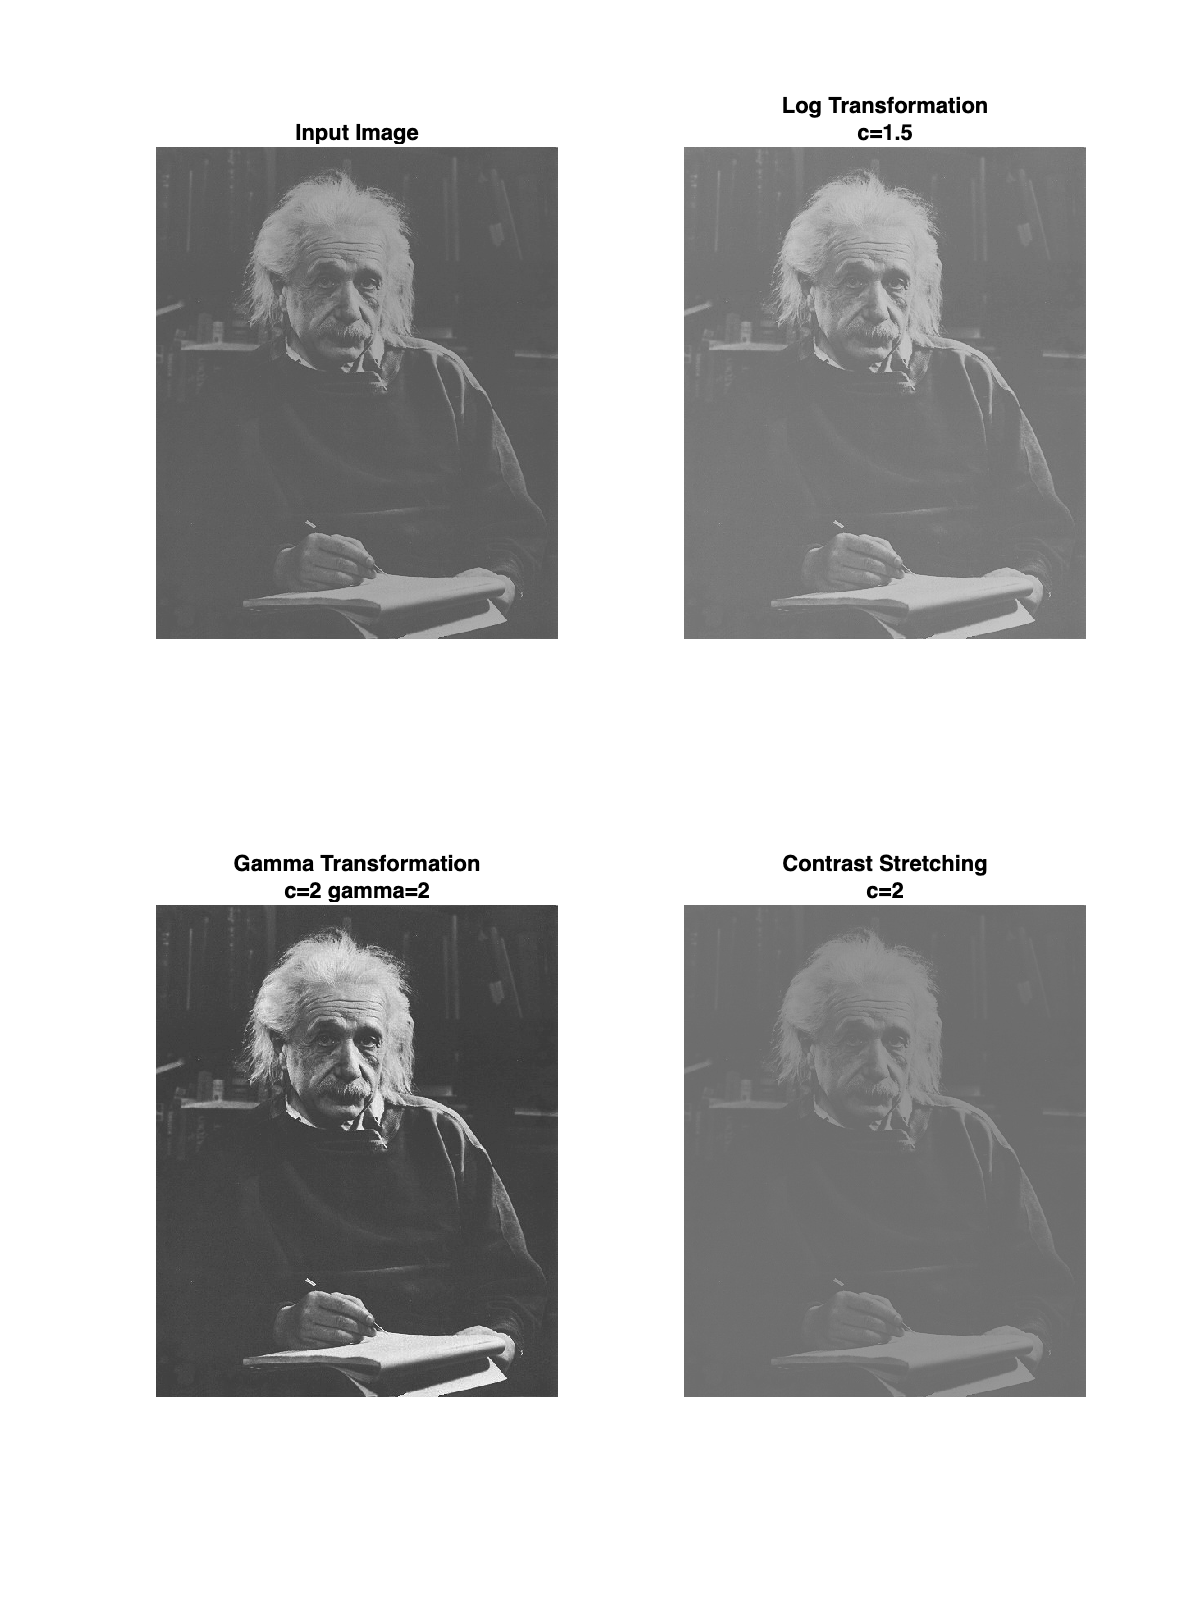

%I /= 255.0;

% Log Transform:
c_log = 1.5 ; % c parameter for log transformation
I_log = c_log.*log(1+I2) ; % insert equation for log transformation here

% Gamma Transform:
c_gamma = 2  ; % c parameter for gamma transformation
gamma_gamma = 2 ; % gamma parameter for gamma transformation
I_gamma =c_gamma.* I2.^gamma_gamma ; % insert equation for gamma transformation here

% Contrast Stretching:
c_contrast =  2; % c parameter for contrast stretching transformation
I_contrast = 1./(1+exp((-c_contrast)*(I2-0.5))) ; % insert equation for contrast stretching transformation here

% Plot:
figure
% Make figure bigger:
set(gcf,'Position',[100,100,750,1000])

% Subplot for original image
% Syntax here is subplot(# of rows, # of columns, subplot #)
% So this is a 2 by 2 grid of subplots, and we're plotting in the 
% first one in the grid
subplot(2,2,1)
imshow(I)
title('Input Image')

% Subplot for log transformed image
subplot(2,2,2)
imshow(I_log)
title(['Log Transformation', 'c='+string(c_log)])

% Subplot for gamma transformed image
subplot(2,2,3)
imshow(I_gamma)
title(['Gamma Transformation','c='+string(c_gamma)+ ' gamma='+string(gamma_gamma)])

% Subplot for contrast stretched image
subplot(2,2,4)
imshow(I_contrast)
title(['Contrast Stretching', 'c='+string(c_contrast)])

% Save figure as a PNG in the current folder
% Include this figure in your homework writeup
saveas(gcf,'HW1_Problem2_Results.png')

% Clear variables, close figures
clear;clc;close all;

## PROBLEM 3

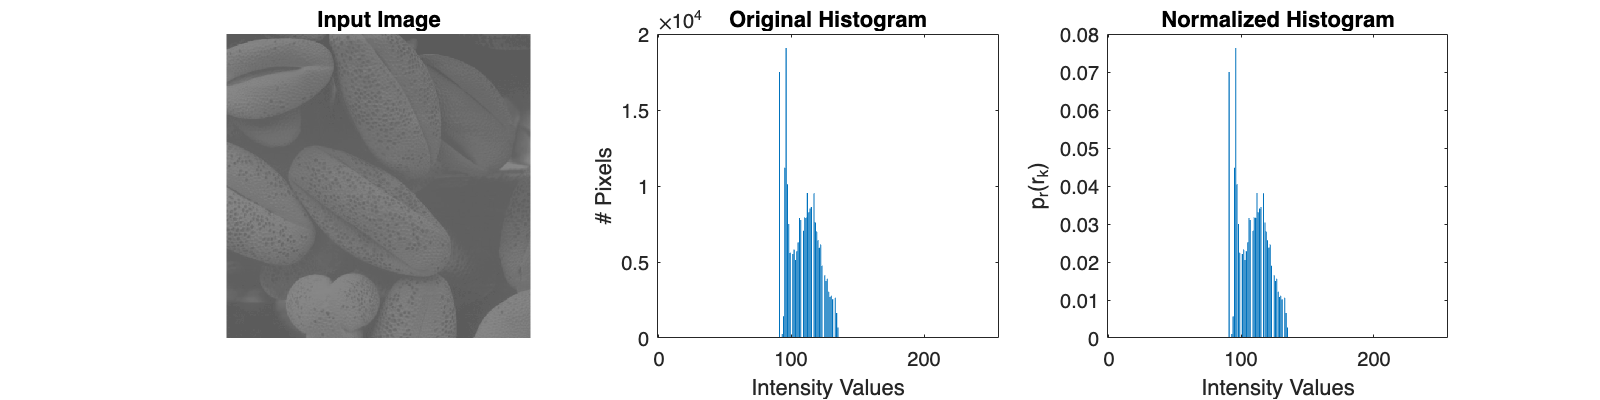

I = imread('hw1img3.tif');

%%%%%%%%%%
% PART a %
%%%%%%%%%%
% Compute histogram of input image
% count[i] is the number of pixels that has intensity intensity[i]
[count, intensity] =imhist(uint8(I));

% Determine number of pixels
M = 500 ; % number of rows
N = 500 ; % number of columns

% Normalize the histogram by dividing by total number of pixels
normalized_counts = count./(M*N);


figure
set(gcf,'Position',[100,100,800,200])

subplot(1,3,1)
imshow(I)
title('Input Image')

subplot(1,3,2)
bar(intensity, count)
title('Original Histogram')
xlabel('Intensity Values')
ylabel('# Pixels')

subplot(1,3,3)
bar(intensity,normalized_counts)
title('Normalized Histogram')
xlabel('Intensity Values')
ylabel('p_r(r_k)')

% Save figure as a PNG in the current folder
% Include this figure in your homework writeup
saveas(gcf,'HW1_Problem3a_Histograms.png')

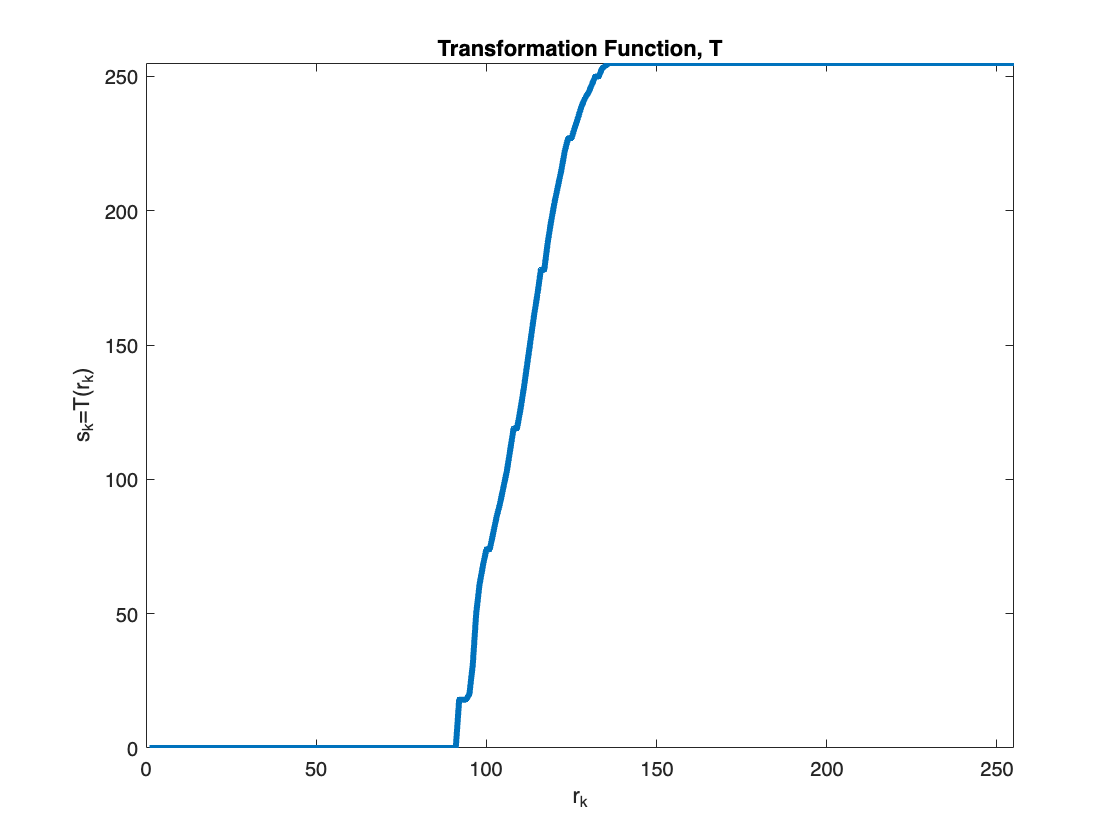

%%%%%%%%%%
% PART b %
%%%%%%%%%%

% Now we need to come up with mapping r_k -> s_k
prob_sum = 0;
s_k = zeros(1,256);

% For r_k = 1,2,3, ... , 256, calculate s_k
r_k = 1:256; 

for i=1:256
    % Keep track of the cumulative sum of the probabilities
    prob_sum =  prob_sum + normalized_counts(r_k(i)); 
    
    % Compute (L-1)* cumulative probability and round to nearest integer
    s_k(r_k(i)) = round((255*prob_sum))  ; 
end

figure
plot(r_k, s_k, "LineWidth",3)
xlabel('r_k')
ylabel('s_k=T(r_k)')
title('Transformation Function, T')
xlim([0,255])
ylim([0,255])

% Save figure as a PNG in the current folder
% Include this figure in your homework writeup
saveas(gcf,'HW1_Problem3b_Transformation.png')

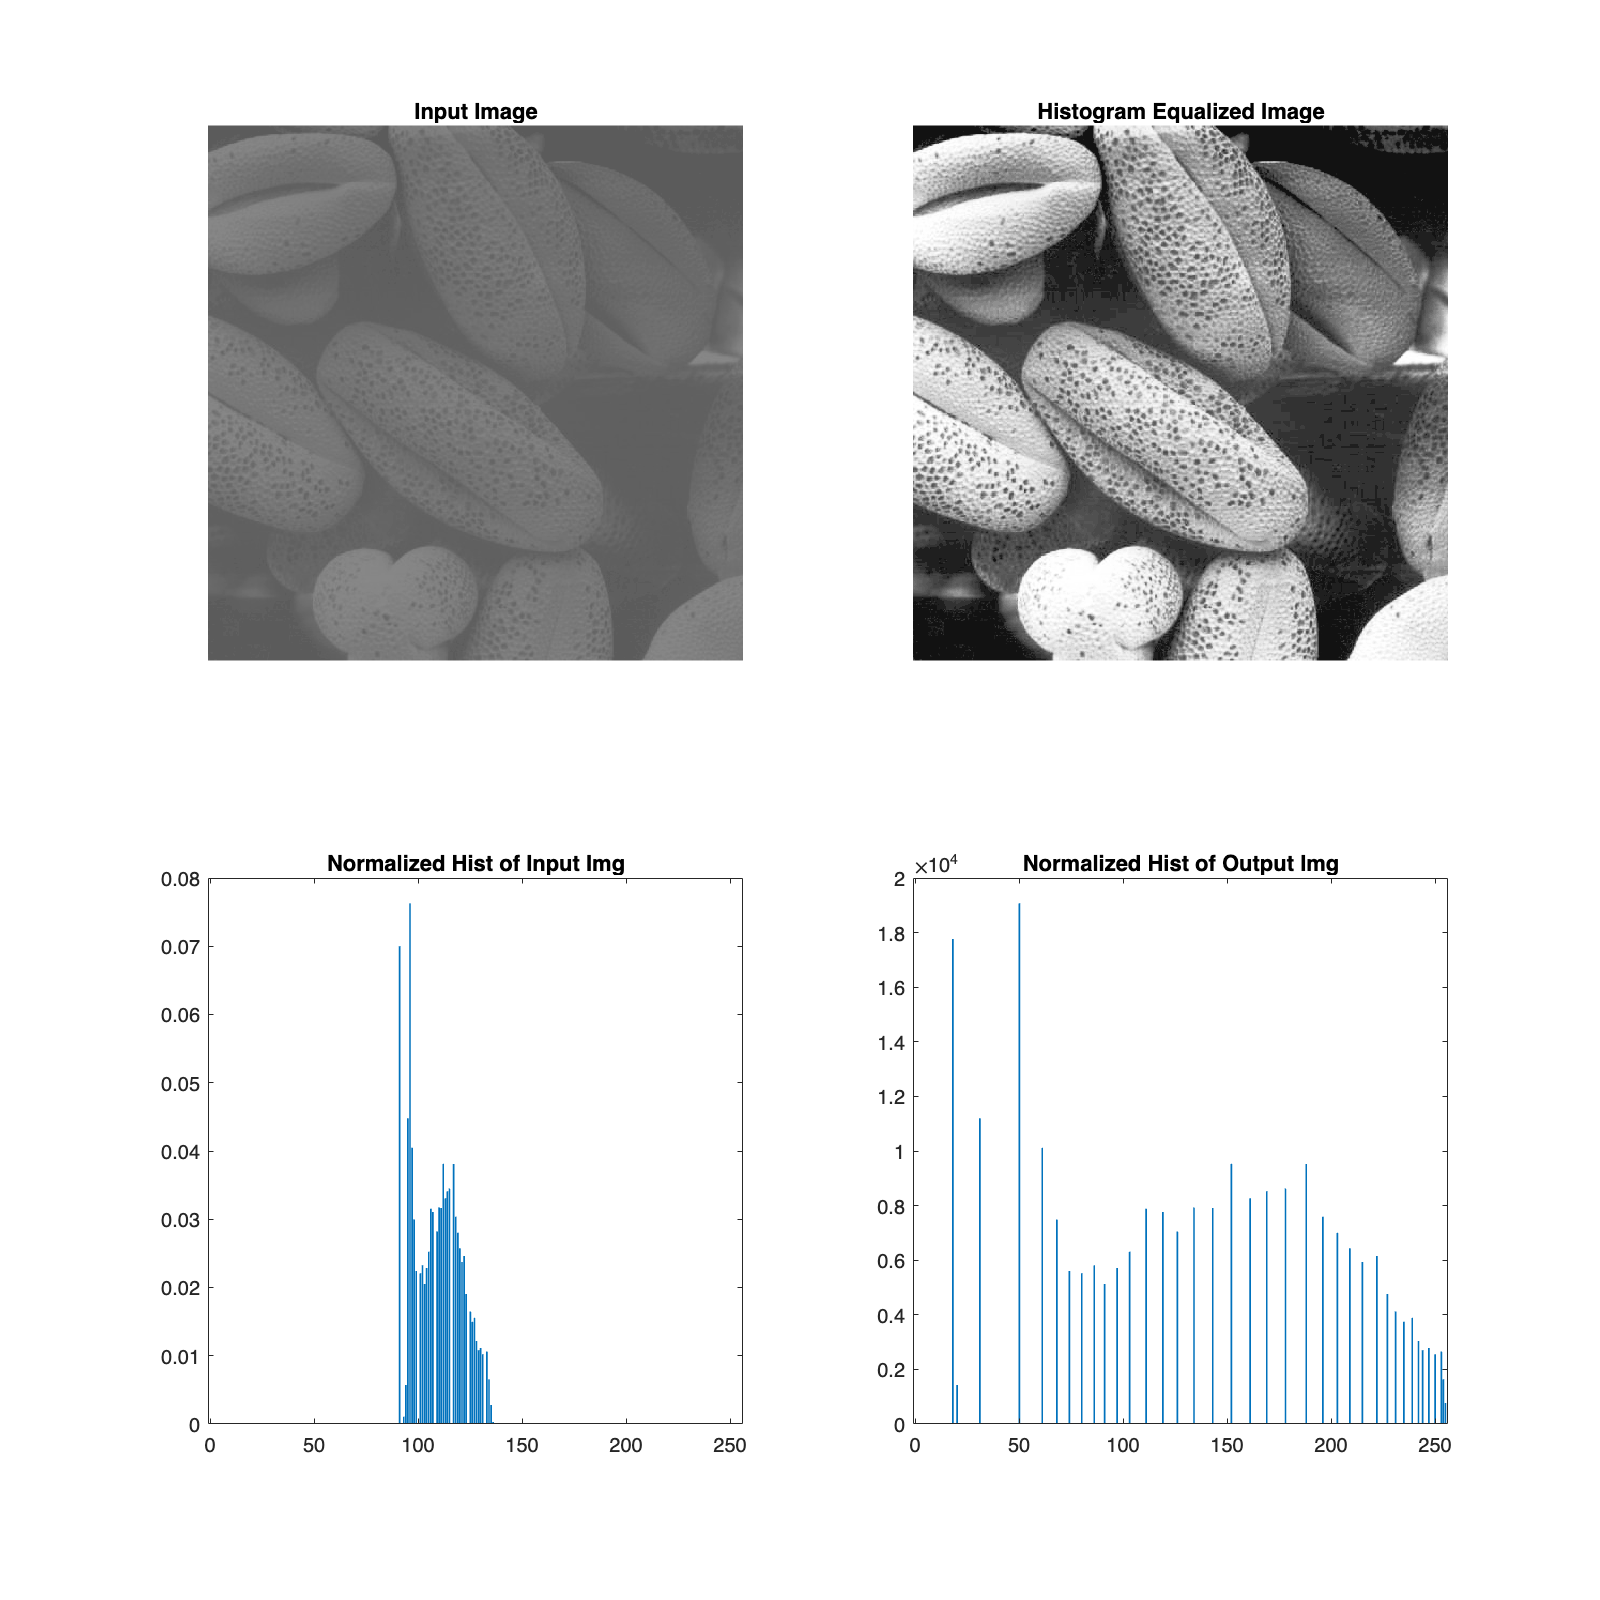

% Initialize an output image with all zeros (and make the type uint8
% since that is what imshow likes
output_image = uint8(zeros(M,N));

% Loop over pixels in the input image, and based on its r_k value, map it 
% to the corresponding s_k value
% Note there is an off by 1 issue because r_k is 1 through 256, but the intensity
% values in I are 0 to 255 
for i=1:M
    for j=1:N
        output_image(i,j) = s_k(I(i,j)+1) ; 
    end
end

% Calculate and normalize the histogram of new histogram equalized output
% image
[equalized_counts,] =imhist(uint8(output_image))  ; 
normalized_equalized_counts = equalized_counts./M*N ;

% Now plot the results
figure
set(gcf,'Position',[100,100,1000,1000])

subplot(2,2,1)
imshow(I)
title("Input Image")

subplot(2,2,2)
imshow(output_image)
title("Histogram Equalized Image")

subplot(2,2,3)
bar(intensity,normalized_counts)
title('Normalized Hist of Input Img')

subplot(2,2,4)

bar(intensity,normalized_equalized_counts)
title('Normalized Hist of Output Img')

% Save figure as a PNG in the current folder
% Include this figure in your homework writeup
saveas(gcf,'HW1_Problem3b_Histograms.png')